#  HW3 Program Assignment

**By:105021202 楊暐之**

## **P1**

### **(a)**


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =x\left\lbrack n-15\right\rbrack \\
\Rightarrow H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=z^{-15} 
\end{array}$$


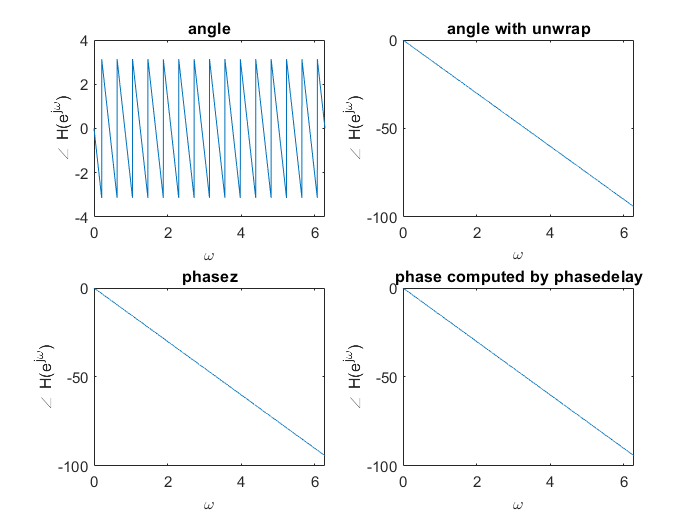

a=[1];
b=zeros(1,15);
b=cat(2,b,[1]);
[H,w]=freqz(b,a,10000,'whole');
[phi]=phasez(b,a,10000,'whole');
[pd]=phasedelay(b,a,10000,'whole');
subplot(2,2,1)
    plot(w,angle(H))
    title("angle")
    xlabel("\omega")
    ylabel("\angle H(e^{j\omega})")
subplot(2,2,2)
    plot(w,unwrap(angle(H)))
    title("angle with unwrap")
    xlabel("\omega")
    ylabel("\angle H(e^{j\omega})")
subplot(2,2,3)
    plot(w,phi)
    title("phasez")
    xlabel("\omega")
    ylabel("\angle H(e^{j\omega})")
subplot(2,2,4)
    plot(w,-pd.*w)
    title("phase computed by phasedelay")
    xlabel("\omega")
    ylabel("\angle H(e^{j\omega})")

### (b)


$$H\left(z\right)=\frac{\left(1+1\ldotp 655z^{-1} +1\ldotp 655z^{-2} +z^{-3} \right)}{\left(1-1\ldotp 57z^{-1} +1\ldotp 264z^{-2} -0\ldotp {4z}^{-3} \right)}$$


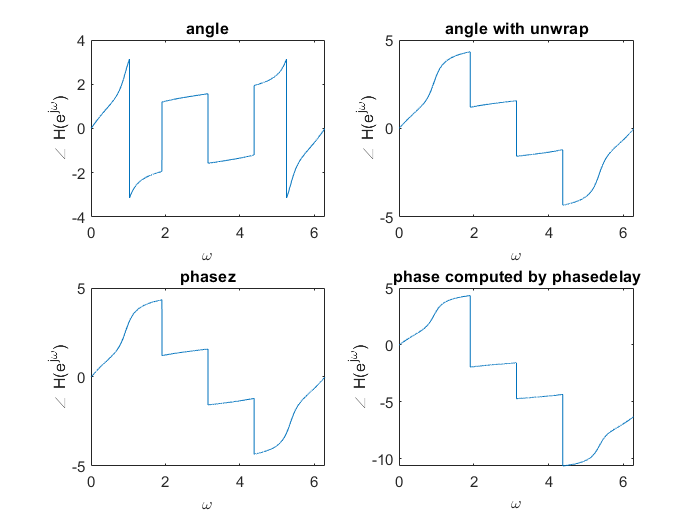

a=[1,1.655,1.655,1];
b=[1,-1.57,1.264,-0.4];
[H,w]=freqz(b,a,10000,"whole");
[phi]=phasez(b,a,10000,"whole");
[pd]=phasedelay(b,a,10000,'whole');
figure
subplot(2,2,1)
    plot(w,angle(H))
    title("angle")
    xlabel("\omega")
    ylabel("\angle H(e^{j\omega})")
subplot(2,2,2)
    plot(w,unwrap(angle(H)))
    title("angle with unwrap")
    xlabel("\omega")
    ylabel("\angle H(e^{j\omega})")
subplot(2,2,3)
    plot(w,phi)
    title("phasez")
    xlabel("\omega")
    ylabel("\angle H(e^{j\omega})")
subplot(2,2,4)
    plot(w,-pd.*w)
    title("phase computed by phasedelay")
    xlabel("\omega")
    ylabel("\angle H(e^{j\omega})")

## P2

### (a)


$$h\left\lbrack n\right\rbrack =\left\lbrack 1,-2,3,-4,0,4,-3,2,-1\right\rbrack$$


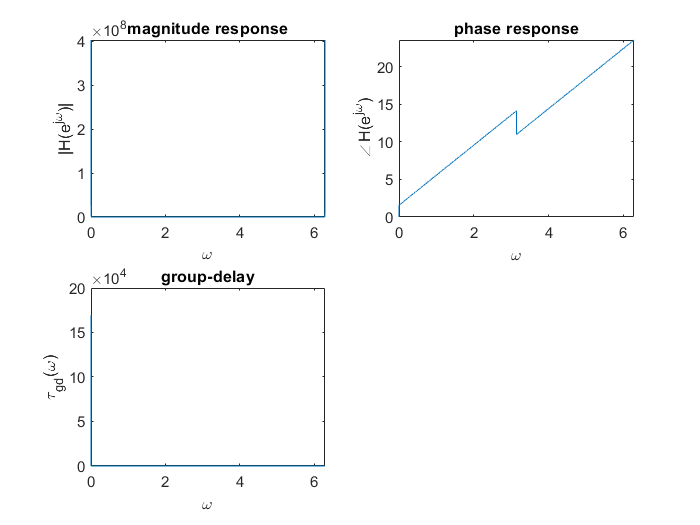

a=[1,-2,3,-4,0,4,-3,2,-1];
b=1;
[H,w]=freqz(b,a,10000,"whole");
[phi]=phasez(b,a,10000,"whole");
[gd]=grpdelay(b,a,10000,"whole");
figure
subplot(2,2,1)
    plot(w,abs(H))
    title("magnitude response")
    xlabel("\omega")
    ylabel("|H(e^{j\omega})|")
subplot(2,2,2)
    plot(w,phi)
    title("phase response")
    xlabel("\omega")
    ylabel("\angleH(e^{j\omega})")
subplot(2,2,3)
    plot(w,gd)
    title("group-delay")
    xlabel("\omega")
    ylabel("\tau_{gd}(\omega)")

### (b)


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =10x\left\lbrack n-10\right\rbrack \\
\Rightarrow H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=10z^{-10} 
\end{array}$$


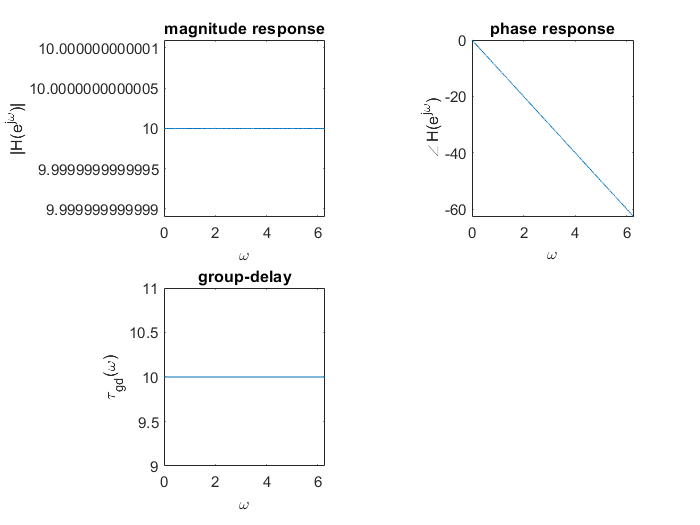

a=1;
b=zeros(1,10);
b=cat(2,b,10);
[H,w]=freqz(b,a,10000,"whole");
[phi]=phasez(b,a,10000,"whole");
[gd]=grpdelay(b,a,10000,"whole");
figure
subplot(2,2,1)
    plot(w,abs(H))
    title("magnitude response")
    xlabel("\omega")
    ylabel("|H(e^{j\omega})|")
subplot(2,2,2)
    plot(w,phi)
    title("phase response")
    xlabel("\omega")
    ylabel("\angleH(e^{j\omega})")
subplot(2,2,3)
    plot(w,gd)
    title("group-delay")
    xlabel("\omega")
    ylabel("\tau_{gd}(\omega)")

## P3


$$\begin{array}{l}
\mathrm{Note}\;\mathrm{that}\;\mathrm{if}\\
H_{\mathrm{min}} \left(z\right)=1+a_1 z^{-1} +\cdots +a_N z^{-N} \;\mathrm{is}\;\mathrm{minimum}\;\mathrm{phase}\\
\mathrm{then}\;H_{\mathrm{max}} \left(z\right)=a_N^* +a_{N-1}^* z^{-1} +\cdots +z^{-N} =z^{-N} H_{\mathrm{min}}^* \left(\frac{1}{z^* }\right)\mathrm{is}\;\mathrm{maximum}\;\mathrm{phase}
\end{array}$$


### (a)


$$H\left(z\right)=\frac{\left(z^2 +2z+0\ldotp 75\right)}{\left(z^2 -0\ldotp 5z\right)}$$


a=[1,-0.5,0];
b=[1,2,0.75];
b_min=polystab(b)

b_min =     1.0000    1.1667    0.3333


b_max=conj(flip(new_b))

b_max =     0.3333    1.1667    1.0000


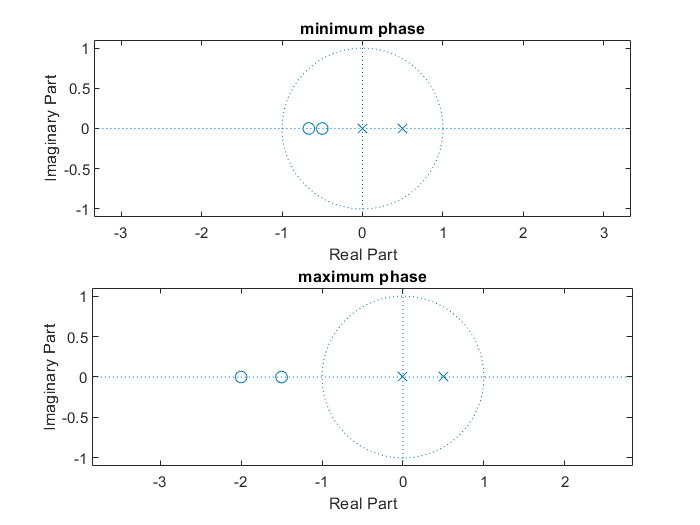


figure
subplot(2,1,1)
    zplane(roots(b_min),roots(a))
    title("minimum phase")
subplot(2,1,2)
    zplane(roots(b_max),roots(a))
    title("maximum phase")

### (b)


$$H\left(z\right)=\frac{\left(1-2\ldotp 4142z^{-1} +2\ldotp 4142z^{-2} -z^{-3} \right)}{1-1\ldotp 8z^{-1} +1\ldotp 62z^{-2} +0\ldotp 729z^{-3} }$$


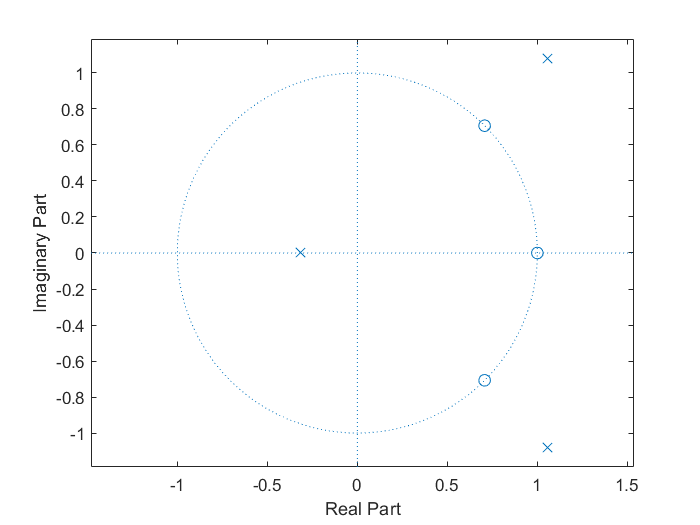

a=[1,-1.8,1.62,0.72];
b=[1,-2.4142,2.4142,-1];
z=roots(b);
p=roots(a);
figure
zplane(z,p)

Since the orginal system has zeros at unit circle , it can't be convert to minimum and maximum phase system

## P4


$$\begin{array}{l}
x_c \left(t\right)=5cos\left(200\pi t+6\pi \right)+4sin\left(300\pi t\right)\;\;\;\\
x\left\lbrack n\right\rbrack \;\mathrm{is}\;\mathrm{the}\;\mathrm{sampling}\;\mathrm{signal}\;\mathrm{of}\;x_c \left(t\right)\;with\;F_s =1kHZ
\end{array}$$


### (a)

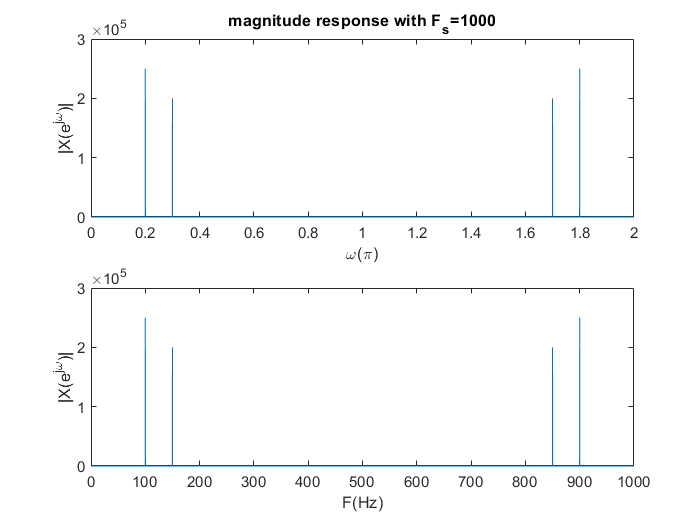

x_c=@(t) 5*cos(200*pi*t+6*pi)+4*sin(300*pi*t);
T=1/1000;
n=[0:T:100];
x=x_c(n);
[X,w]=freqz(x,1,10000,"whole");
figure
subplot(2,1,1)
    plot(w/pi,abs(X))
    title("magnitude response with F_s=1000")
    xlabel("\omega(\pi)")
    ylabel("|X(e^{j\omega})|")
subplot(2,1,2)
    F=w/2/pi/T;
    plot(F,abs(X))
    xlabel("F(Hz)")
    ylabel("|X(e^{j\omega})|")

$x_c \left(t\right)\;$can be recovered from $x\left\lbrack n\right\rbrack$ since sampling frequency >Nyquist rate

### (b)

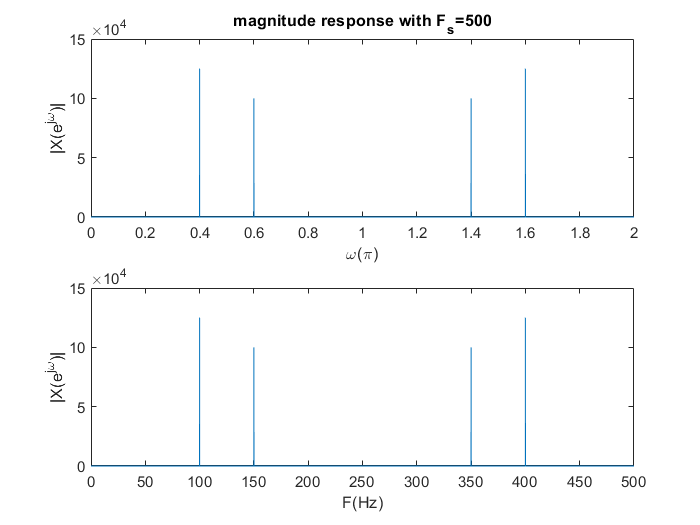

T=1/500;
n=[0:T:100];
x=x_c(n);
[X,w]=freqz(x,1,10000,"whole");
figure
subplot(2,1,1)
    plot(w/pi,abs(X))
    title("magnitude response with F_s=500")
    xlabel("\omega(\pi)")
    ylabel("|X(e^{j\omega})|")
subplot(2,1,2)
    F=w/2/pi/T;
    plot(F,abs(X))
    xlabel("F(Hz)")
    ylabel("|X(e^{j\omega})|")

$x_c \left(t\right)\;$can be recovered from $x\left\lbrack n\right\rbrack$ since sampling frequency >Nyquist rate

### (c)

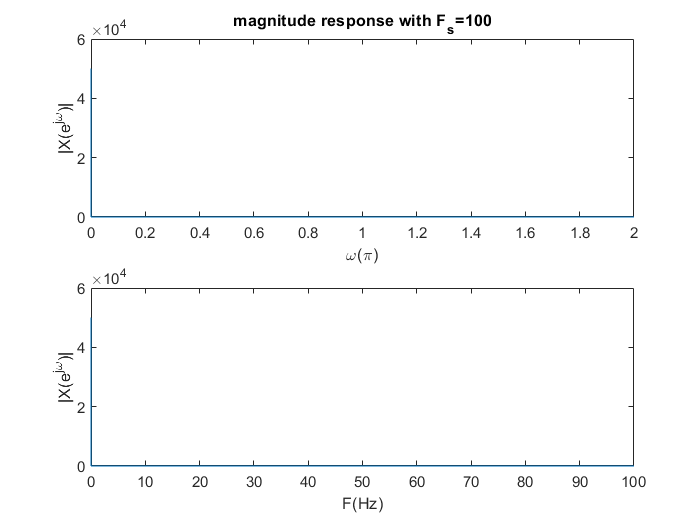

T=1/100;
n=[0:T:100];
x=x_c(n);
[X,w]=freqz(x,1,10000,"whole");
figure
subplot(2,1,1)
    plot(w/pi,abs(X))
    title("magnitude response with F_s=100")
    xlabel("\omega(\pi)")
    ylabel("|X(e^{j\omega})|")
subplot(2,1,2)
    F=w/2/pi/T;
    plot(F,abs(X))
    xlabel("F(Hz)")
    ylabel("|X(e^{j\omega})|")

$x_c \left(t\right)\;$can't be recovered from $x\left\lbrack n\right\rbrack$ since sampling frequency <Nyquist rate and some informations are elimiated due to overlapping $i\ldotp e\ldotp$ it occurs aliasing

### (d)

To ensure $x_c \left(t\right)\;$can be recovered from $x\left\lbrack n\right\rbrack$ , we need $F_s >300\left(Hz\right)$